# Laboratorio final robótica 2021-1

### UNAL 

Kevin Andres Ramirez Gutierrez - 

David Andrés Rivas Gonzalez - 

Jefferson David Rojas Avellaneda - jedrojasav

Manuel Alejandro Rojas Cubillos - 

### Modelos

- Se hace el análisis geométrico del robot y se llega a la siguiente tabla de parámetros DHmod:

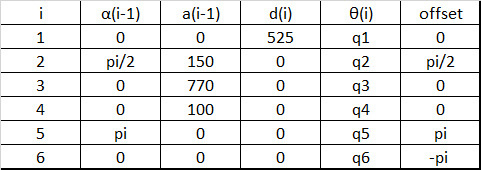

Una vez obtenida la tabla se procede a crear el modelo del robot usando el toolbox de peter corke por medio de las funciones Link y serialLink

clear; clc;
l1 = 525; l2=150; l3=770; l4=100; l5=740; l6=100; 
q1 = 0; q2=0; q3=0; q4=0; q5=0; q6=0;  % Valores Home 
q =  [q1 q2 q3 q4 q5 q6];

ws = [-1500 1500 -1500 1000 -50 2400];
plot_options = {'workspace',ws,'scale',.5,'view',[135 45],'tilesize',2,'ortho','lightpos',[100 100 100]};

L(1) = Link('revolute', 'alpha', 0,     'a',  0,    'd',    l1, 'offset',       0,  'qlim', [-pi pi],'modified');
L(2) = Link('revolute', 'alpha', pi/2,  'a', l2,    'd',    0,  'offset',    pi/2,  'qlim', [-pi/2 8*pi/9], 'modified') ;
L(3) = Link('revolute', 'alpha', 0,     'a', l3,    'd',    0,  'offset',       0,  'qlim', [-17*pi/18 29*pi/18], 'modified');
L(4) = Link('revolute', 'alpha', pi/2,  'a', l4,    'd',    l5,  'offset',       0,  'qlim', [-10*pi/9 10*pi/9], 'modified');
L(5) = Link('revolute', 'alpha', pi/2,  'a',  0,    'd',    0,  'offset',     pi,  'qlim', [-7*pi/4 7*pi/4], 'modified');
L(6) = Link('revolute', 'alpha', pi/2,  'a',  0,    'd',    l6,  'offset',   pi/2,  'qlim', [-5*pi/2 5*pi/2], 'modified');

Robot = SerialLink (L,'name','Fanuc','plotopt',plot_options)

 
Robot = 
 
Fanuc (6 axis, RRRRRR, modDH, fastRNE)                           
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        525|          0|          0|          0|
|  2|         q2|          0|        150|      1.571|      1.571|
|  3|         q3|          0|        770|          0|          0|
|  4|         q4|        740|        100|      1.571|          0|
|  5|         q5|          0|          0|      1.571|      3.142|
|  6|         q6|        100|          0|      1.571|      1.571|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0            

Se observa que la tabla de parámetros obtenida es igual a la que se planteó en un inicio por lo que se procede a ver el robot en forma gráfica:

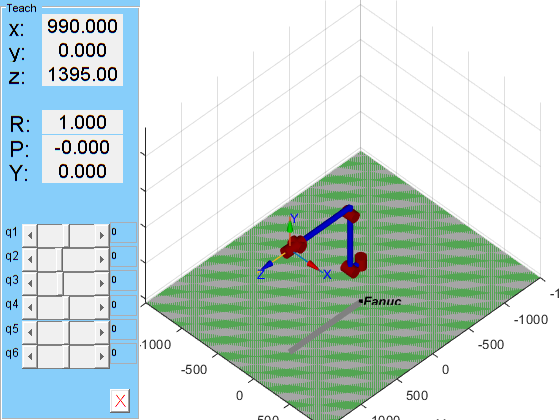

Robot.teach(q)

### Modelo geométrico directo

- Modelo geometrico directo del robot asignado usando MTH.

clear
threshold = 1e-10;
%syms L1 L2 L3 L4 L5 L6;

% Primero se definen las longitudes de las articulaciones y el espacio de
% trabajo
L1=525;L2=150;L3=770;L4=100;L5=740;L6=100;
ws= [-1500 1500 -1500 1000 -50 2400];

%Se define cada una de las articulaciones con sus parametros y se grafica
%el robot
plot_options = {'workspace',ws,'scale',.5,'view',[125 25], 'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
L(1) = Link('revolute','alpha',0,'a',0,'d',L1,'offset', 0, 'qlim', [0 2*pi], 'modified');
L(2) = Link('revolute','alpha',pi/2,'a',L2,'d',0,'offset', pi/2, 'qlim',  [-pi/2 8*pi/9], 'modified');
L(3) = Link('revolute','alpha',0,'a',L3,'d',0,'offset', 0, 'qlim', [-17*pi/18 29*pi/18], 'modified');
L(4) = Link('revolute','alpha',pi/2,'a',L4,'d',L5,'offset', 0, 'qlim', [-10*pi/9 10*pi/9], 'modified');
L(5) = Link('revolute','alpha',pi/2,'a',0,'d',0,'offset', pi, 'qlim', [-7*pi/4 7*pi/4], 'modified');
L(6) = Link('revolute','alpha',pi/2,'a',0,'d',L6,'offset', pi/2, 'qlim', [-5*pi/2 5*pi/2], 'modified');

Robot5 = SerialLink(L,'name','Fanuc M-161B','plotopt',plot_options)

 
Robot5 = 
 
Fanuc M-161B (6 axis, RRRRRR, modDH, fastRNE)                    
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        525|          0|          0|          0|
|  2|         q2|          0|        150|      1.571|      1.571|
|  3|         q3|          0|        770|          0|          0|
|  4|         q4|        740|        100|      1.571|          0|
|  5|         q5|          0|          0|      1.571|      3.142|
|  6|         q6|        100|          0|      1.571|      1.571|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0           

- MTH para cada eslabón.

%Se define y muestra la MTH para cada eje
syms gamma1 gamma2 gamma3 gamma4 gamma5 gamma6
MTH_01 = mapSymType(vpa(L(1).A(gamma1),2), 'vpareal', @(x) piecewise(abs(x)<=threshold, 0, x))

$$MTH\_01 = \left(\begin{array}{cccc} \cos\left(\gamma_{1}\right) & -1.0\,\sin\left(\gamma_{1}\right) & 0 & 0\\ \sin\left(\gamma_{1}\right) & \cos\left(\gamma_{1}\right) & 0 & 0\\ 0 & 0 & 1.0 & 525.0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

MTH_12 = mapSymType(vpa(L(2).A(gamma2),2), 'vpareal', @(x) piecewise(abs(x)<=threshold, 0, x))

$$MTH\_12 = \left(\begin{array}{cccc} \cos\left(\gamma_{2}+1.570796326734125614166259765625\right) & -1.0\,\sin\left(\gamma_{2}+1.570796326734125614166259765625\right) & 0 & 150.0\\ 0 & 0 & -1.0 & 0\\ \sin\left(\gamma_{2}+1.570796326734125614166259765625\right) & \cos\left(\gamma_{2}+1.570796326734125614166259765625\right) & 0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

MTH_23 = vpa(mapSymType(vpa(L(3).A(gamma3),2), 'vpareal', @(x) piecewise(abs(x)<=threshold, 0, x)),2)

$$MTH\_23 = \left(\begin{array}{cccc} \cos\left(\gamma_{3}\right) & -1.0\,\sin\left(\gamma_{3}\right) & 0 & 770.0\\ \sin\left(\gamma_{3}\right) & \cos\left(\gamma_{3}\right) & 0 & 0\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

MTH_34 = vpa(mapSymType(vpa(L(4).A(gamma4),2), 'vpareal', @(x) piecewise(abs(x)<=threshold, 0, x)),2)

$$MTH\_34 = \left(\begin{array}{cccc} \cos\left(\gamma_{4}\right) & -1.0\,\sin\left(\gamma_{4}\right) & 0 & 100.0\\ 0 & 0 & -1.0 & -740.0\\ \sin\left(\gamma_{4}\right) & \cos\left(\gamma_{4}\right) & 0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

MTH_45 = mapSymType(vpa(L(5).A(gamma5),2), 'vpareal', @(x) piecewise(abs(x)<=threshold, 0, x))

$$MTH\_45 = \left(\begin{array}{cccc} -1.0\,\cos\left(\gamma_{5}\right) & \sin\left(\gamma_{5}\right) & 0 & 0\\ 0 & 0 & -1.0 & 0\\ -1.0\,\sin\left(\gamma_{5}\right) & -1.0\,\cos\left(\gamma_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

MTH_56 = mapSymType(vpa(L(6).A(gamma6),2), 'vpareal', @(x) piecewise(abs(x)<=threshold, 0, x))

$$MTH\_56 = \left(\begin{array}{cccc} \cos\left(\gamma_{6}+1.570796326734125614166259765625\right) & -1.0\,\sin\left(\gamma_{6}+1.570796326734125614166259765625\right) & 0 & 0\\ 0 & 0 & -1.0 & -100.0\\ \sin\left(\gamma_{6}+1.570796326734125614166259765625\right) & \cos\left(\gamma_{6}+1.570796326734125614166259765625\right) & 0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

-  Formulación del modelo geométrico directo (cinemática directa)

%Se establece la MTH para el efector del robot, se calcula y se muestra
MTH6T=[1 0 0 0;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
Robot5.tool = MTH6T;
H = vpa(mapSymType(vpa(MTH_01*MTH_12*MTH_23*MTH_34*MTH_45*MTH_56*MTH6T, 2), 'vpareal', @(x) piecewise(abs(x)<=threshold, 0, x)),2)

- Ubicación efector final

%Se obtienen los valores para los valores de articulacion

q=[0.5, 0.2, 0.4, 0.5, 0, 1.5];
%q=[-pi/2, 0.3, 0, pi/2, 0.4, 1.2];
%q=[0, 1, -0.5 2 1 0.5];
%q=[-1, -0.3, -pi/5, 0.4 0.2 1];
TCP = Robot5.fkine(q)

TCP = 	1.0e+03 *

   -0.0003    0.0006    0.0007    0.5562
   -0.0006   -0.0007    0.0004    0.3039
    0.0008   -0.0003    0.0006    1.8365
         0         0         0    0.0010


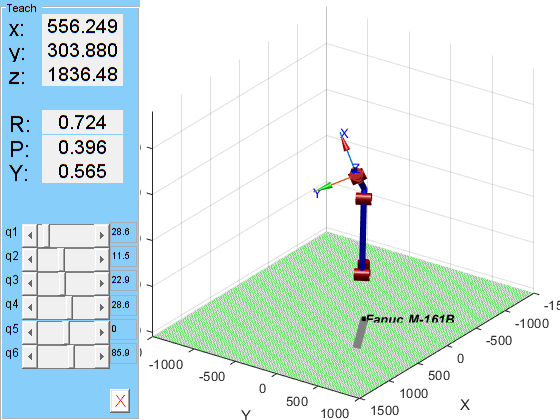

Robot5.teach(q); 

- Posición en coordenadas cartesianas y la orientación en ángulos fijos (Corke).

% Se hace la conversion a Coordenadas Cartesianas
    TCP_cart=transl(TCP)

TCP_cart = 	1.0e+03 *

    0.5562
    0.3039
    1.8365


% Se hace la conversion a Coordenadas Ángulos fijos
    TCP_rpy=tr2rpy(TCP)

TCP_rpy =    -0.6112    0.8100   -1.9435


### Modelo geométrico inverso

- Haciendo uso del metodo geométrico visto en clase juntoo con el método algebráico encontramos los valores de los ángulos de las juntas en diferentes posiciones.

%Posicion 1    
x0=1000;y0=600;z0=1000;roll=0;pitch=90;yaw=180;

%Posicion 2    
%x0=67;y0=-911;z0=1895;roll=-26;pitch=-10;yaw=53;
%Posicion 3    
%x0=1306;y0=430;z0=1279;roll=-133;pitch=43;yaw=111;
%Posicion 4    
%x0=323;y0=107;z0=1988;roll=-22;pitch=42;yaw=-173;



ROT=rpy2r(roll,pitch,yaw,'deg');

p0=[x0;y0;z0];
pw=p0 -L5*ROT(:,3);
xw=pw(1);
yw=pw(2);
zw=pw(3);
r=sqrt(xw^2+yw^2);
Lxy=r-L2;
Lz=zw-L1;
Lp=sqrt(Lxy^2+Lz^2);

q1=atan2(yw,xw)

q1 = 1.1619


alpha=atan2(abs(Lz),abs(Lxy));
cosB=(L3^2+Lp^2-L5^2)/(2*L3*Lp);
senB=sqrt(1-cosB^2);
beta=atan2(abs(senB),abs(cosB));
q2=-((pi/2)-(alpha+beta))

q2 = 0.2413


cosY=(L3^2+L5^2-Lp^2)/(2*L3*L5);
senY=sqrt(1-cosY^2);
gama=atan2(senY,cosY);
phi=pi-gama;
q3=(pi/2)-phi

q3 = -0.6187


MTH03=L(1).A(q1)*L(2).A(q2)*L(3).A(q3)

MTH03 = 	1.0e+03 *

    0.0001   -0.0004    0.0009   -0.0135
    0.0003   -0.0009   -0.0004   -0.0312
    0.0009    0.0004    0.0000    1.2727
         0         0         0    0.0010


MTH36=MTH03^-1*TCP

MTH36 =     0.4542   -0.4569    0.7648  720.9019
    0.8908    0.2207   -0.3972 -288.6722
    0.0127    0.8617    0.5073  389.5643
         0         0         0    1.0000


ang=tr2eul(MTH36,'deg') %Corresponden a los valores de q4 q5 y q6 

ang =   -27.4426   59.5187   90.8453


Realizamos el mismo procedimiento para las 4 posiciones  de la máquina diferentes y completamos la tabla:

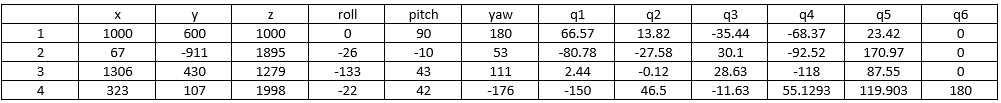

### Modelo diferencial de primer orden